# Getting Started with EGH446 Simulation Environment

## Description

This simulation environment contains several toolboxes to allow the simulation ground and aerial robots. This includes:

- Robotics toolbox [1] and Mobile Robotics Simulation Toolbox [2].

- 2D kinematic models for robot geometries such as differential drive, three, and four-wheeled vehicles, including forward and inverse kinematics

- Configurable lidar and object detector simulators 

- Visualization of robotic vehicles and sensors in occupancy grid maps

- MATLAB and Simulink examples and documentation

## System Requirements

This version of the toolbox has been tested in MATLAB 9.6 (R2019a or R2019b).

Product dependencies are:

- MATLAB

- Simulink

- Stateflow

- Robotics System Toolbox

- Navigation Toolbox

- Control System Toolbox + Model Predictive Control Toolbox (optional)

- Reinforcement Learning Toolbox + Deep Learning Toolbox (optional)

- Simscape + Simscape Multibody (optional)

## Before you start

Before you are able to use the hyperlinks and examples in this guide, you must execute startupAerial or startupGround. This will add to your current path all directories and functions linked to this guide.

## How to Start an Aerial Robot

In the source directory,  execute

startupAerial

'startupAerial' is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\Pierce\Documents\EGH446\egh446_simEnv2020\egh446_simEnv2020\sim_env

Change the MATLAB current folder or add its folder to the MATLAB path.

 this should bring a simulink environment as shown below

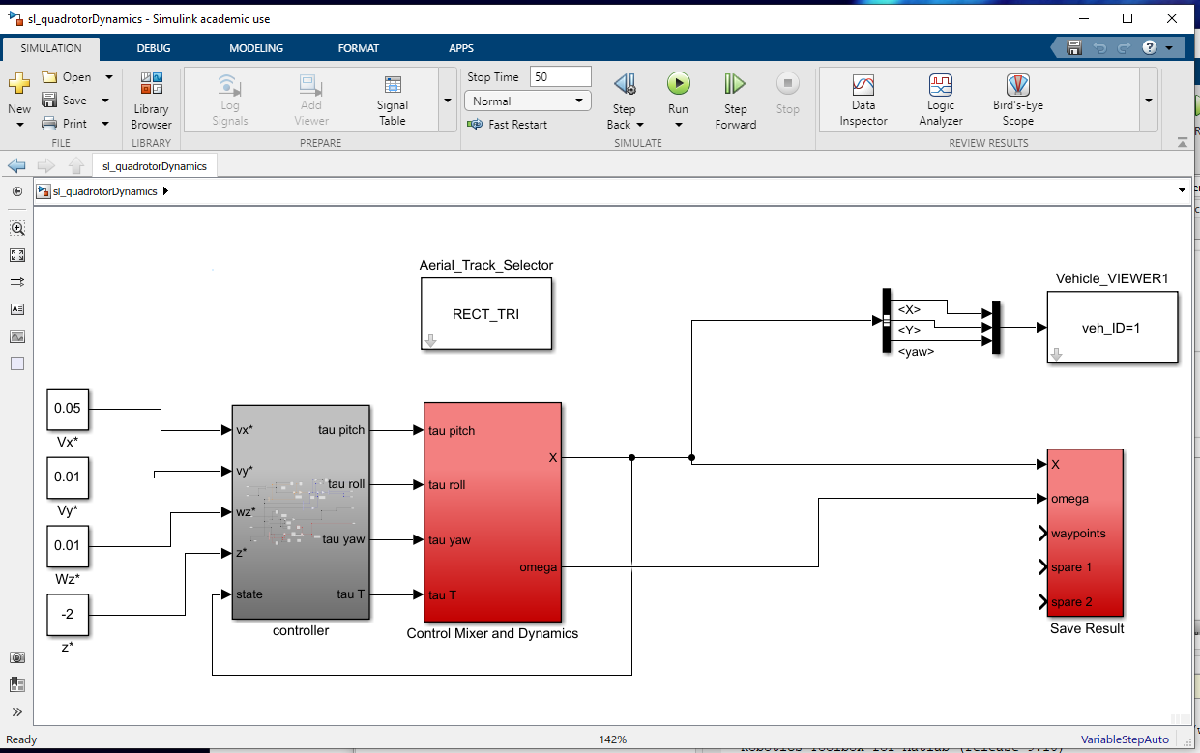

- The block** Aerial Track Selector** allows you to select an excel file containing waypoint that define specific trajectories. By default this file is called ***aerial_robot_waypoints.xlsx. ***This block also has the possibility to specify parameters for a pure pursuit navigation approach.

- The block  **Vehicle Viewer **display waypoints and vehicle trajecotry

- The block **Save Result **save a number of states and variables to a *.mat file.This block can used to save the outcome of the simulation to the workspapce and also a *.mat file.

Please note that this environment contains the dynamics and controls of a standard quadrotor. It has a basic automatic control that stabilises velocities and altitude. Executing the simulink environment will cause the drone to drift by default unless reference values are adjusted.

## How to start a Ground Robot

In the source directory,  execute

startupGround

this should bring a simulink environment as shown below

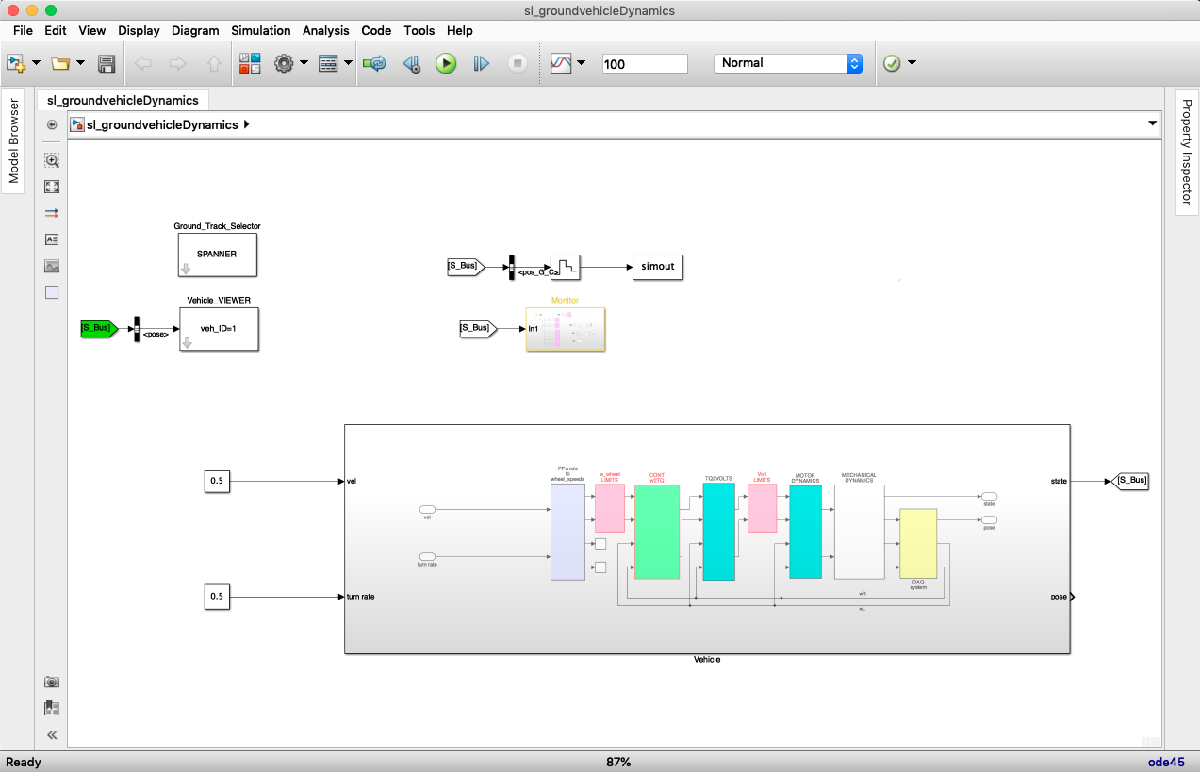

- The block** Ground Track Selector** allows you to select an excel file containing waypoint that define specific trajectories. By default this file is called ***ground_robot_waypoints.xlsx. ***This block also has the possibility to specify parameters for a pure pursuit navigation approach.

- The block  **Vehicle Viewer **display waypoints and vehicle trajecotry.

- The block **Save Result (simout) **save a number of states and variables to a *.mat file (position by default).

- The block** Monitor** can be used to plot (observe) some of the states.

Please note that this environment contains the dynamics and internal regulators (linear and angular veocity controllers) for a [ground differential robot](matlab:edit bh_DDR_model_EOM_derivation). The robot accepts linear velocity commands [-0.5 , 0.5] m/s and turn rates [-pi/2 , pi/2] rad/s. Higher turn rates can be achieved however this could impact system stability.

## Library Componets

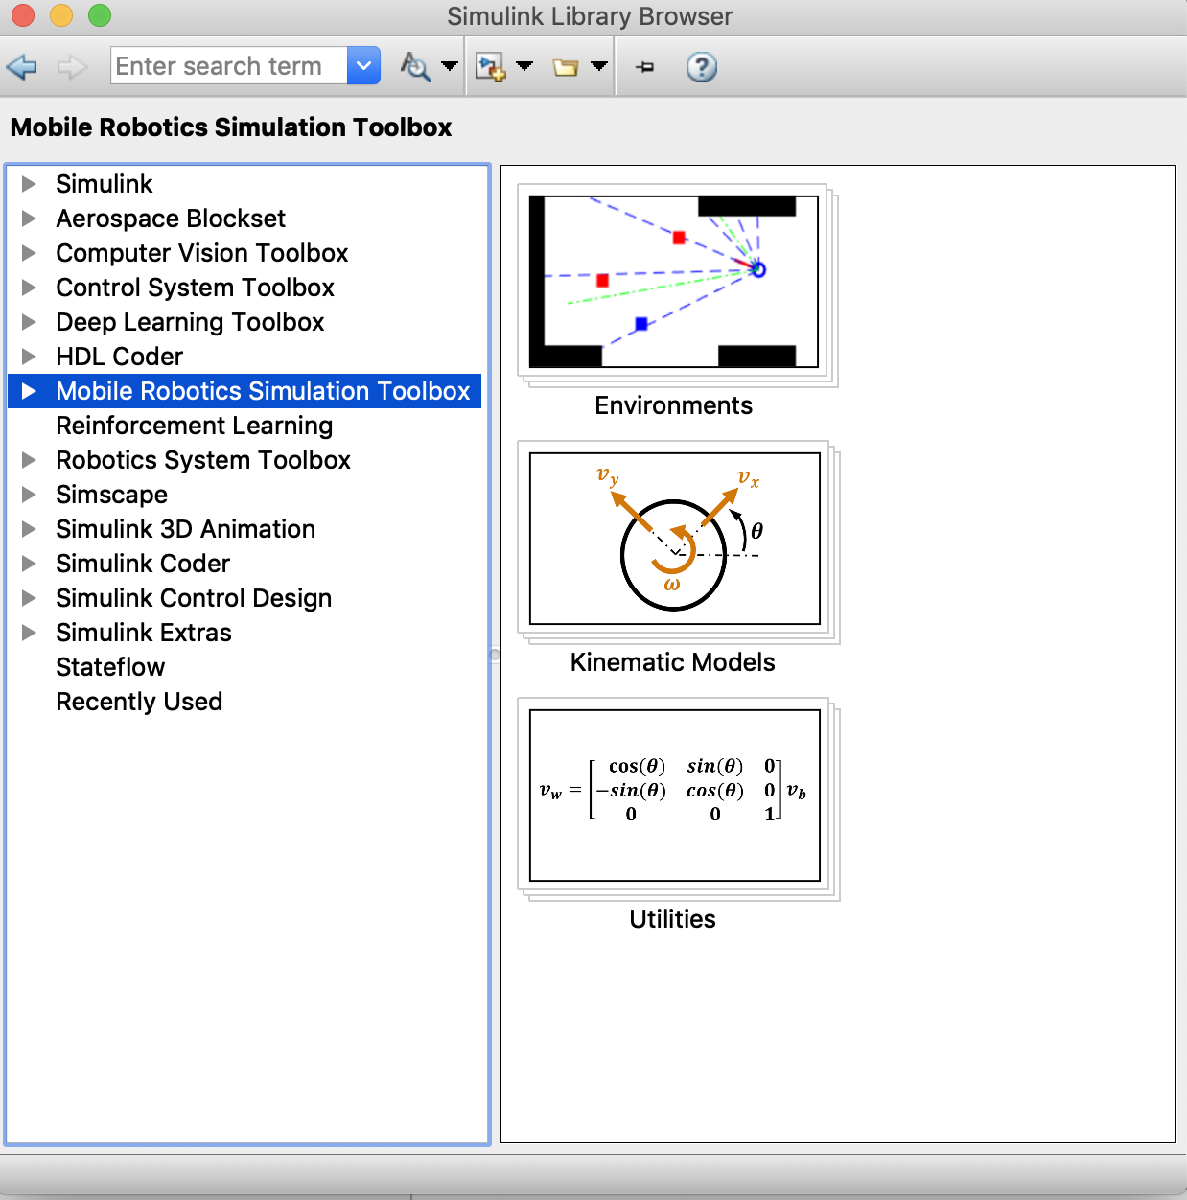

The environment provides a number of simulink blocks to

- Simulate sensors and detectors 

- Ground robot models

- Utilities for conversion

These block can be used to add a laser to your robot and simulate object detection among other tasks.

## Mobile Robotics Simulation Toolbox Documentation

Kinematic Models

- [Differential Drive](matlab:edit mrsDocDifferentialDrive)

- [Triple Omniwheel](matlab:edit mrsDocTripleOmniwheel)

- [Generic Omniwheel](matlab:edit mrsDocGenericOmniwheel)

- [Four-Wheel Steering](matlab:edit mrsDocFourWheelSteer)

- [Four-Wheel Mecanum](matlab:edit mrsDocFourWheelMecanum)

Environment Models

- [Robot Visualizer](matlab:edit mrsDocVisualizer2D)

- [Multi-Robot Environment](matlab:edit mrsDocMultiRobotEnv)

Sensor Models

- [Lidar Sensor](matlab:edit mrsDocLidarSensor)

- [Multi-Robot Lidar Sensor](matlab: edit mrsDocMultiRobotLidarSensor)

- [Object Detector](matlab:edit mrsDocObjectDetector)

- [Robot Detector](matlab:edit mrsDocRobotDetector)

## Examples

For simple examples outlining usage of individual models, sensors, or visualizers, please refer to the documentation links above.

Below is a list of all the application examples, which can be found in the `examples` directory of the toolbox.

Simulink Examples

- [Waypoint following using the Pure Pursuit Algorithm (Differential Drive)](matlab:mrsDiffDrivePurePursuitModel)

- [Waypoint following using the Pure Pursuit Algorithm (Four-Wheel Steering)](matlab:mrsFourWheelPurePursuitModel)

Application Examples

- [Robot Soccer Simulation](matlab:multiRobotSoccer)

- [Navigation Behavior with Vector Field Histogram (VFH) Obstacle Avoidance](matlab: navBehaviorWithVFH)

- [Navigation Behavior with Reinforcement Learning Based Obstacle Avoidance](matlab:navBehaviorWithRL)

## **References**

[1] Robotics Toolbox. [http://petercorke.com/wordpress/toolboxes/robotics-toolbox](http://petercorke.com/wordpress/toolboxes/robotics-toolbox) 

[2] Mobile Robotics Simulation Toolbox. Copyright 2018-2019 The MathWorks, Inc. [https://github.com/mathworks-robotics/mobile-robotics-simulation-toolbox](https://github.com/mathworks-robotics/mobile-robotics-simulation-toolbox) 